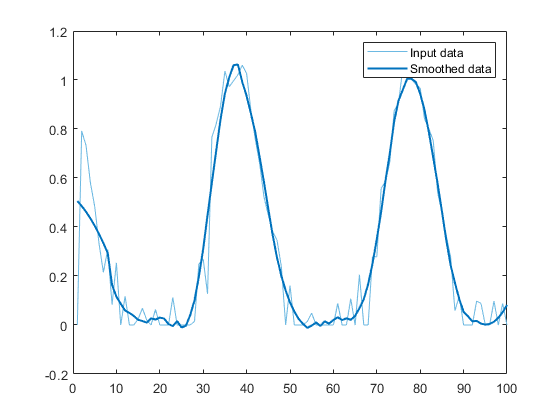

% Smooth input data
smoothedData = smoothdata(senal1,'sgolay','SmoothingFactor',0.25);

% Display results
clf
plot(senal1,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

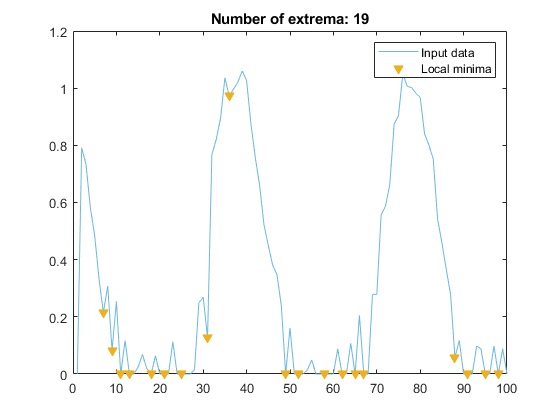

% Find local minima
minIndices = islocalmin(senal1);

% Display results
clf
plot(senal1,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local minima
plot(find(minIndices),senal1(minIndices),'v','Color',[237 177 32]/255,...
    'MarkerFaceColor',[237 177 32]/255,'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(minIndices))])
hold off
legend